# Identification

clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');
cs.setMaxAcceleration(15);
cs.setRestTime(0.1);

## 1. Joint 2 Identification

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.1;
ampiezza_portante=20;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=60;

Sommo i due segnali

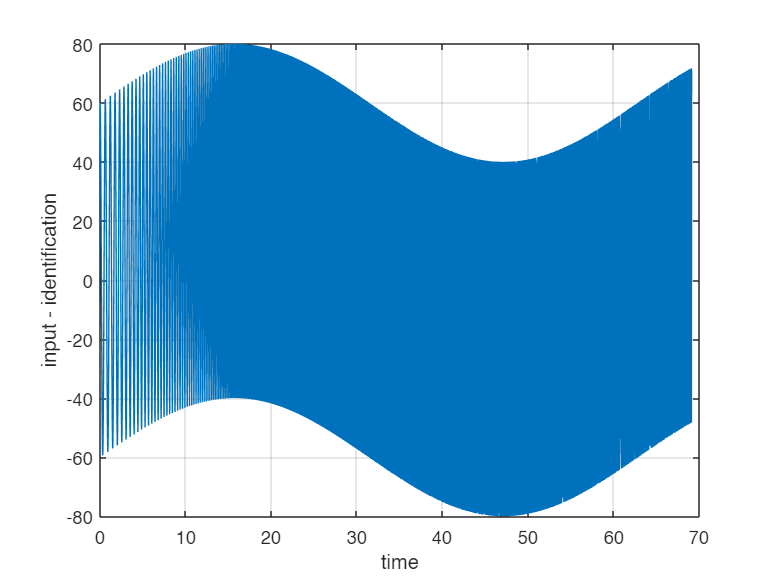

control_action=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

### 1.1 Simulazione sistema

I tratti con velocità vicina allo 0 hanno una dinamica chiaramente non lineare, l'approssimazione lineare nelle frequenze esplorare dal segnale eccitante in quei punti sarà scarsa.

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
k=50/(1/360*2*pi);
x=x0;
s=tf('s');
Ti=10;
PI=k*(1+1/(Ti*s));
controller1=Controller(st,PI,[-600 600]);
torque=zeros(length(control_action),2);
process_output_id2=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(1));
    [x,t(idx,1)]=cs.openloop([still_ca control_action(idx)]);
    process_output_id2(idx,:) = x;
    torque(idx,:) = [still_ca control_action(idx)];
end
toc

Elapsed time is 67.215948 seconds.


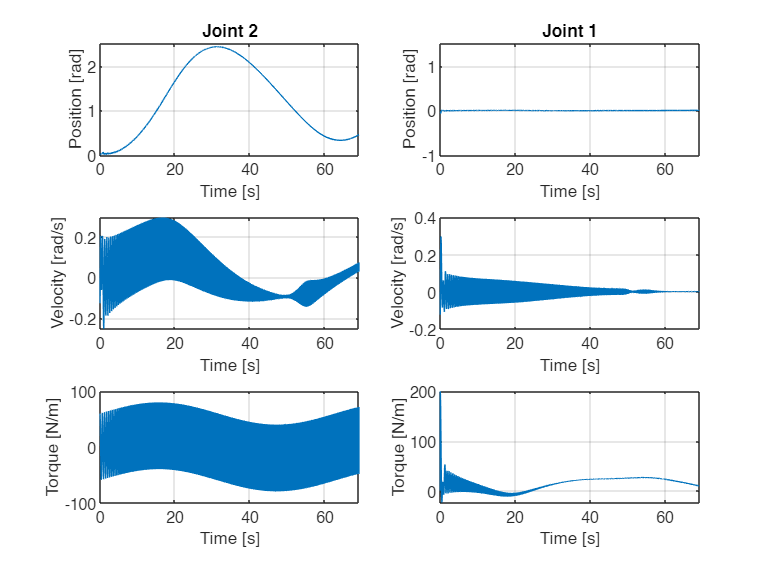

figure(1)
% Joint 2
subplot(3,2,1)
plot(t,process_output_id2(:,2))
xlabel('Time [s]')
ylim([0,2.5])
xlim([0,t(end)])
ylabel('Position [rad]')
title('Joint 2')
grid on

subplot(3,2,3)
plot(t,process_output_id2(:,4))
xlim([0,t(end)])
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
grid on

subplot(3,2,5)
plot(t,torque(:,2))
xlim([0,t(end)])
xlabel('Time [s]')
ylabel('Torque [N/m]')
grid on

% Join 1
subplot(3,2,2)
plot(t,process_output_id2(:,1))
xlim([0,t(end)])
xlabel('Time [s]')
ylim([-1,1.5])
ylabel('Position [rad]')
title('Joint 1')
grid on

subplot(3,2,4)
plot(t,process_output_id2(:,3))
xlim([0,t(end)])
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
grid on

subplot(3,2,6)
plot(t,torque(:,1))
xlim([0,t(end)])
xlabel('Time [s]')
ylabel('Torque [N/m]')
grid on
% Salvataggio della figura
set(gcf,'renderer','painters')

%exportgraphics(gcf,'D:\Github\scara-robot\img\id_joint2.emf')

Nota: le frequenze in prossimità dei cambi di velocità sono stimate peggio (è opportuno che: 1) ripetere con segnali diversi 2) in validazione il signale sia diverso).

### 1.2 Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification_data=iddata(process_output_id2(:,4),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification_data);
figure(3)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

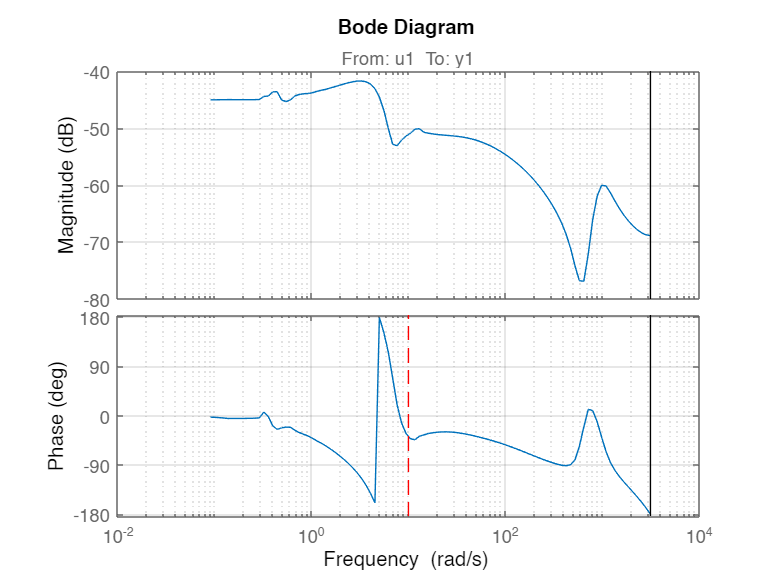

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### 1.3 Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=10;
wpeso1=pi/st;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_j2 = ssest(freq_resp_ident,4,opts);
modello_discreto_j2 = ssest(freq_resp_ident,4,'Ts',st,opts);
modello_continuo_tf_j2=tf(modello_continuo_j2)

modello_continuo_tf_j2 =
 
  From input "u1" to output "y1":
                                         
  0.6838 s^3 + 77.57 s^2 + 2.438e05 s    
                                         
                               + 1.664e06
                                         
  ---------------------------------------
                                         
  s^4 + 520 s^3 + 9.901e05 s^2           
                                         
                    + 8.96e07 s + 0.03434
                                         
 
Continuous-time transfer function.



save modello_j2 modello_continuo_tf_j2

### 1.4 Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo_j2,modello_discreto_j2, bode_opts)

visualizzo solo il range di frequenze di interesse

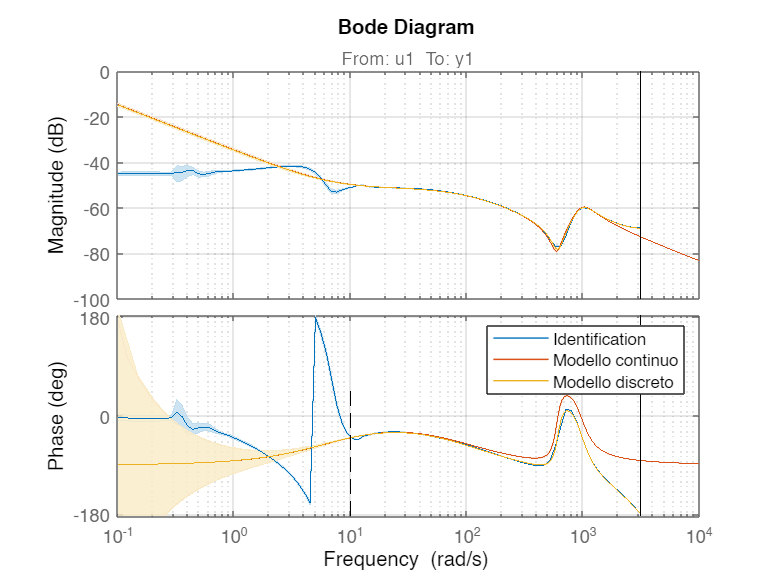

xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')
% Salvataggio della figura
set(gcf,'renderer','painters')

%exportgraphics(gcf,'D:\Github\scara-robot\img\model_joint2.emf')

clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');
load modello_j2.mat


## 2. Joint 1 Identification

### 2.1 Controller joint 2

figure
G = tf(modello_continuo_tf_j2);

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 100 rad/s)

wc=180;

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/20; % pulsazione azione integrale
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*G,wc));
C_old=Kp*Co

C_old =
 
  93.62 s + 842.6
  ---------------
     0.1111 s
 
Continuous-time transfer function.



### 2.2 Filtro notch

damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.86e-12                 1.00e+00       1.86e-12         5.37e+11    
 -9.43e+01                 1.00e+00       9.43e+01         1.06e-02    
 -2.13e+02 + 9.51e+02i     2.18e-01       9.75e+02         4.70e-03    
 -2.13e+02 - 9.51e+02i     2.18e-01       9.75e+02         4.70e-03    



wn=1100;
xci_z=0.38; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.8;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
subplot(1,2,1)
bode(notch)
grid on
Kp=1/abs(freqresp(Co*G*notch,wc));
C=Kp*Co*notch;
save draftController C
subplot(1,2,2)
bode(C_old*G); hold on
margin(C*G); hold off
grid on
legend('Loop','Loop with Notch filter')
getPeakGain(feedback(1,C*G))

ans = 1

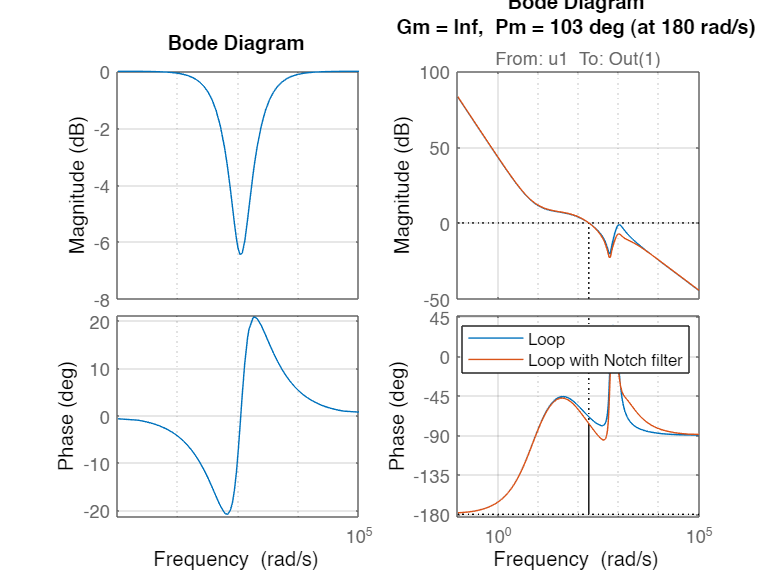

set(gcf,'renderer','painters')
%exportgraphics(gcf,'notch_controller_joint2.emf')

### 2.3 Generazione Chirp

Costruzione segnale Chirp per primo giunto

omega_portante_j1=0.1;
ampiezza_portante_j1=20;
T_portante=2*pi/omega_portante_j1;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante_j1*sin(omega_portante_j1*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione_j1 = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione_j1=80;

Sommo i due segnali

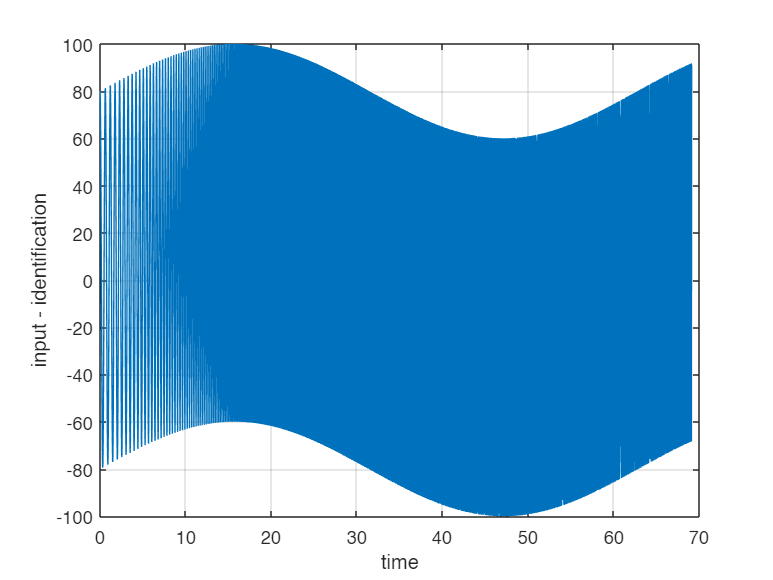

control_action_j1=portante + control_action_identificazione_j1*ampliezza_identificazione_j1;
figure
plot(t,control_action_j1)
xlabel('time')
ylabel('input - identification')
grid on

Identificazione giunto 1

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
x=x0;


controller1=Controller(st,C,1);
controller1.setUMax(600);
torque=zeros(length(control_action_j1),2);
process_output_id1=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(2));
    [x,t(idx,1)]=cs.openloop([control_action_j1(idx) still_ca]);
    process_output_id1(idx,:) = x;
    torque(idx,:) = [control_action_j1(idx) still_ca];
end
toc

Elapsed time is 65.029911 seconds.


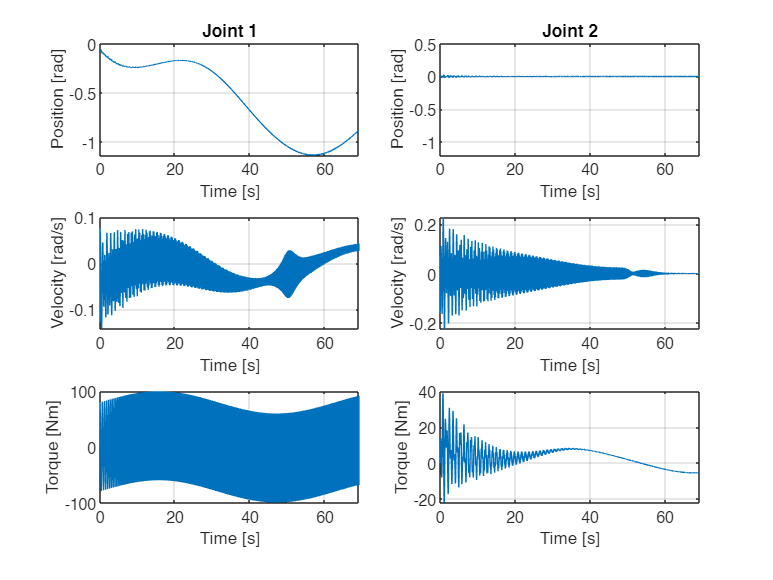

figure
subplot(3,2,1)
plot(t,process_output_id1(:,1))
xlabel('Time [s]')
xlim([0,t(end)])
ylabel('Position [rad]')
title('Joint 1')
grid on

subplot(3,2,3)
plot(t,process_output_id1(:,3))
xlabel('Time [s]')
xlim([0,t(end)])
ylabel('Velocity [rad/s]')
grid on

subplot(3,2,5)
plot(t,torque(:,1))
xlabel('Time [s]')
xlim([0,t(end)])
ylabel('Torque [Nm]')
grid on

subplot(3,2,2)
plot(t,process_output_id1(:,2))
xlabel('Time [s]')
xlim([0,t(end)])
ylim([-1.2,0.5])
ylabel('Position [rad]')
title('Joint 2')
grid on

subplot(3,2,4)
plot(t,process_output_id1(:,4))
xlabel('Time [s]')
xlim([0,t(end)])
ylabel('Velocity [rad/s]')
grid on

subplot(3,2,6)
plot(t,torque(:,2))
xlim([0,t(end)])
xlabel('Time [s]')
ylabel('Torque [Nm]')
grid on

% Salvataggio della figura
set(gcf,'renderer','painters')

% exportgraphics(gcf,'D:\Github\scara-robot\img\id_joint1.emf')

### 2.4 Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification_data=iddata(process_output_id1(:,3),control_action_j1,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident_j1 = spafdr(identification_data);
figure(3)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident_j1, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

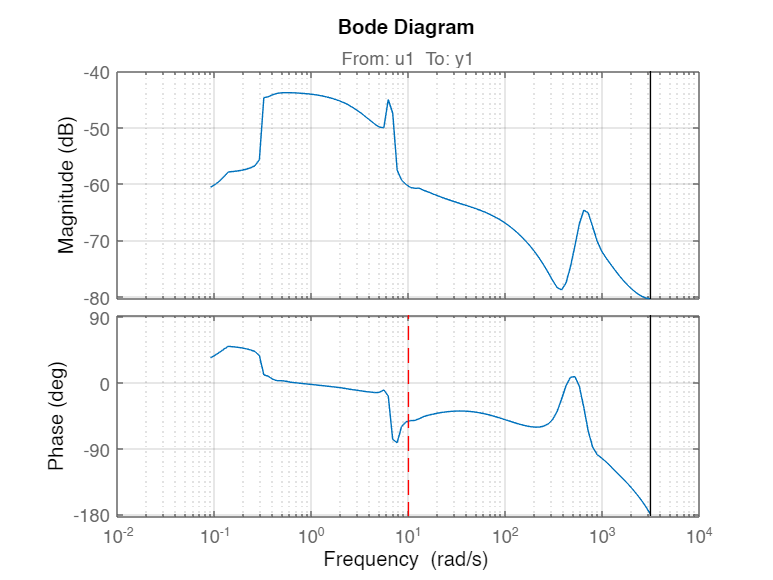

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### 2.5 Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident_j1.Frequency),1);
wpeso0=10;
wpeso1=1000;
peso(freq_resp_ident_j1.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident_j1.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_j1 = ssest(freq_resp_ident_j1,4,opts);
modello_discreto_j1 = ssest(freq_resp_ident_j1,4,'Ts',st,opts);
modello_continuo_tf_j1=tf(modello_continuo_j1)

modello_continuo_tf_j1 =
 
  From input "u1" to output "y1":
                                         
  0.177 s^3 + 36.76 s^2 + 2.699e04 s     
                                         
                               + 2.965e05
                                         
  ---------------------------------------
                                         
  s^4 + 297.9 s^3 + 4.438e05 s^2         
                                         
                 + 3.874e07 s + 3.127e-05
                                         
 
Continuous-time transfer function.



save modello_j1 modello_continuo_tf_j1

### 2.6 Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident_j1, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo_j1,modello_discreto_j1, bode_opts)

visualizzo solo il range di frequenze di interesse

xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

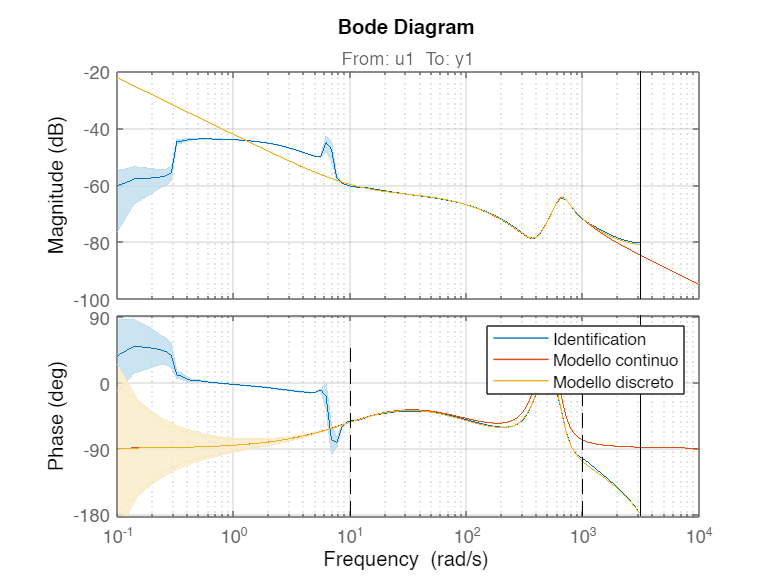

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')
% Salvataggio della figura
set(gcf,'renderer','painters')

%exportgraphics(gcf,'D:\Github\scara-robot\img\model_joint1.emf')